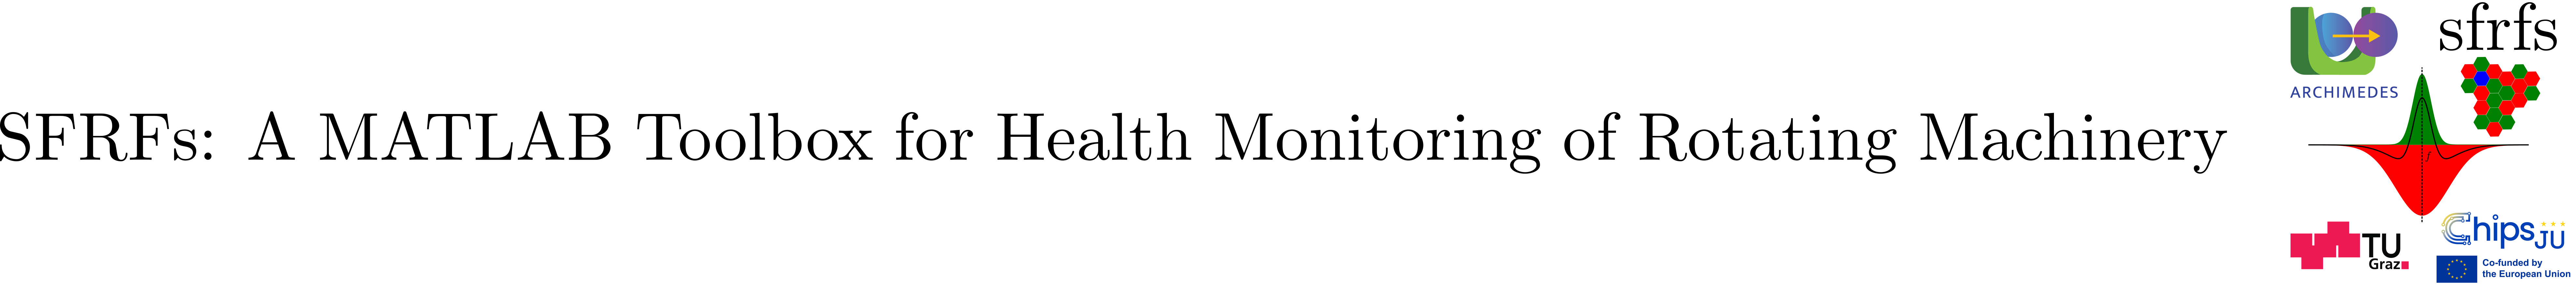

# FaultBandsExtractSchema

## Summary

`FaultBandsExtractSchema` centralizes the field-name constants used in the struct output of `extractBands()`, ensuring stable downstream access.

## Description

This schema is intentionally independent of table schemas to keep computational outputs stable even if tabular representations change. It standardizes how extracted band metadata and band matrices are represented in

struct form.

### Defined fields 

**Operating-point and bookkeeping**

- `FAULTGROUP. `Numeric fault group identifier.

- `SPEED. `Operating speed associated with the extracted bands (Hz).

- `LOAD. `Operating load associated with the extracted bands (kN).

- `NUMBEROFBANDS. `Total number of band entries extracted.

**Band-matrix column conventions**

- `MINFREQCOLUMN. `Column index for minimum frequency.

- `MAXFREQCOLUMN. `Column index for maximum frequency.

- `HARMONICCOLUMN. `Column index for harmonic number.

- `SIDEBANDCOLUMN. `Column index for sideband index.

**Indexing helpers**

- `CHARACTERISTICFREQUENCYINDEX. `Row index of the characteristic component (fundamental, no sideband).

**Extracted band matrices**

- `CENTERBANDSMATRIX. `Sorted matrix of center frequency bands.

- `SURROUNDBANDSMATRIX. `Sorted matrix of surround frequency bands.

### Notes

- These fields describe a **struct output**; they do not define any table column names.

- The center/surround matrices are expected to follow the column conventions defined by the `*COLUMN` fields above.

### See also

[`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx')), [`tables.FaultBandsTableSchema`](matlab:open('./FaultBandsTableSchema.mlx')), [structs.`OpponentBandsSchema`](matlab:open('./OpponentBandsSchema.mlx'))

## `Example`

% Example: call FaultFrequencyBands.extractBands and access fields

import tables.FaultBandsTableSchema
import dicts.BandMapSchema
import structs.OpponentBandsSchema
import structs.FaultBandsExtractSchema

ft = SFRFsParametersRollingBearings.INNER_RACE_FAULT_TYPE_NAME;
fg = BearingFrequencyBands.faultTypeGroups(ft);
ds = BearingFrequencyBands.faultTypeDescriptions(ft);

% One receptive-field band record (containers.Map)
b = struct();
b.(OpponentBandsSchema.CENTER) = [95, 105];
b.(OpponentBandsSchema.SURROUND) = [90, 110];

m = containers.Map('KeyType','char','ValueType','any');
m(BandMapSchema.BANDS) = b;
m(BandMapSchema.HARMONIC) = 1;
m(BandMapSchema.SIDEBAND) = 0;
m(BandMapSchema.LABEL) = "1" + string(BearingFrequencyBands.BPFI_CODE);

% Minimal fault-bands table row
T = table();
T.(FaultBandsTableSchema.FAULTGROUP) = fg;
T.(FaultBandsTableSchema.DESCRIPTION) = ds;
T.(FaultBandsTableSchema.SPEED) = 35;
T.(FaultBandsTableSchema.LOAD) = 12;
T.(FaultBandsTableSchema.RECEPTIVEFIELDBANDS) = { {m} };
disp(T);

    FaultGroup       Description        Speed    Load    ReceptiveFieldBands
    __________    __________________    _____    ____    ___________________

        2         "Inner Race Fault"     35       12         {1×1 cell}     




% Extract bands struct
bands = FaultFrequencyBands.extractBands(T, 1);

% Access via FaultBandsExtractSchema (no hard-coded field names)
C = bands.(FaultBandsExtractSchema.CENTERBANDSMATRIX);
S = bands.(FaultBandsExtractSchema.SURROUNDBANDSMATRIX);
idx = bands.(FaultBandsExtractSchema.CHARACTERISTICFREQUENCYINDEX);

disp("Center bands matrix: " + mat2str(C));

Center bands matrix: [95 105 1 0]


disp("Surround bands matrix: " + mat2str(S));

Surround bands matrix: [90 110 1 0]


disp("Index of characteristic component: " + idx);

Index of characteristic component: 1


## API documentation

### MATLAB help

help structs.FaultBandsExtractSchema

 FaultBandsExtractSchema  Field names for FaultFrequencyBands.extractBands.
 
  Defines the struct fields returned by extractBands(). This schema is
  independent of table schemas to keep computational outputs stable even
  if tabular representations change.
 
  See also: FaultFrequencyBands, tables.FaultBandsTableSchema

    Documentation for structs.FaultBandsExtractSchema



## Source code

The source of the class can be found in [FaultBandsExtractSchema](matlab:open('../../+structs/FaultBandsExtractSchema.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).